# Macro III: Problem Set 3

Deadline: Friday, 17/09/2018

Aluno: Bruno Tebaldi de Queiroz Barbosa (C174887)

Professor: Tiago Cavalcanti

Source code disponível em: [https://github.com/btebaldi/Macro3/tree/master/PSet_03](https://github.com/btebaldi/Macro3/tree/master/PSet_02)

## Questao 2

## Item A

Limpeza de variaveis

clearvars
clc

Cria um processo de markov com as caracteristicas especificadas.

sigma = ((1-0.98^2)*0.621)^0.5;
mkv = MarkovProcess(0.98, sigma ,2,7,0);
mkv.AR.sigma2_y

ans = 0.6210

[chain,state] = MarkovSimulation(mkv.TransitionMatrix, 1000, mkv.StateVector, 3);

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000


% plot(chain);

## Item b

As *households* resolvem o seguinte problema de maximização:


$$max\left\{E_0\left[\sum_{t=0}^\infty \beta^t \left( \frac{C_t^{1-\sigma_c}}{1-\sigma_c} + \gamma \frac{(1-l_t)^{1-\sigma_l}}{1-\sigma_l} \right) \right] \right\}$$


sujeito a


$$a_{t+1} + c_t = (1+r)a_t + w_{t}z_{t}$$



$$\sigma_c, \sigma_l > 0$$



$$a_{t+1} \ge -\frac{wz}{r}$$


## Item C

As firmas representativas resolvem o seguinte problema


$$max \left\{ K_t^\alpha N_t^{1-\alpha} -w_tN_t -r_tK_t\right\}$$


## Item D

O Equilibrio recursivo stacionario é uma taxa de juros, r, uma taxa de salario, w, uma função política, g(a,z), e uma distribuição estacionária. Tal que:

- Dado r e w, a função política g(a,z) resolve o problema do consumidor;

- Dado r e w, a firma representativa maximiza os lucros;  $w = F_N(K;N)$ e $r + \delta = F_K(K;N)$

- Markets clear: $K_0 = \sum_{z,a}\lambda(a,z)a$ $N = \pi ' z$

- A distribuição estacionária $\lambda(a,z)$ é induzida por $(P; z)$ e $g(a; z)$


$$\lambda(B) = \sum_{X=[a_L, a_U] \times Z \in B}Q(X,B)$$


## Item E

Algoritimo:

- Definir um valor para $r_j \in (-\delta, 1/\beta -1)$;

- Determinar o capital-labor ratio $r = F_K(k) -\delta$

- Determinar w:  $w = F_L(k)$;

- Resolver o problema dos consumidores e determinar $a_{t+1}(a;z)$, $c_t(a;z)$, $l_t(a;z)$;

- Calcular a distribuição estacionária $\lambda(a;z)$

- Calcula a oferta de capital agregado e oferta de trabalho;

- Avaliar o excesso de capital $D(r)=k - \frac{K}{L}$;

- Se $D(r) > 0$, então $r_{j+1} > r_j$; se $D(r) < 0$, então $r_{j+1} < r_j$.

- Interate until convergence.

eps = 1e-5;

eco_param.alpha = 0.4;
eco_param.beta = 0.96;
eco_param.delta = 0.08;
eco_param.gamma = 0.75;

eco_param.sigma_c = 2;
eco_param.sigma_l = 2;

% Determina os parametros r e w da economia
eco_param.r_UpperBound = 1/eco_param.beta -1;
eco_param.r_LowerBond = -eco_param.delta;
eco_param.r = (eco_param.r_UpperBound + eco_param.r_LowerBond)/2;
eco_param.r_tilda = eco_param.r + eco_param.delta;

% Determina os Grids
WageShocks.Values = exp(mkv.StateVector);
WageShocks.Grid.Min = min(WageShocks.Values);
WageShocks.Grid.Max = max(WageShocks.Values);
WageShocks.Grid.N = mkv.QtdStates;
WageShocks.PI = mkv.TransitionMatrix;

% Determina as caracteristicas do grid de trabalho
Labor.Grid.N = 20;
Labor.Grid.Min = 0.01;
Labor.Grid.Max = 1;
Labor.Values = linspace(Labor.Grid.Min, Labor.Grid.Max, Labor.Grid.N);

for nContador =1:100

## Definir um valor para $r_j \in (-\delta, 1/\beta -1)$;

    eco_param.r = (eco_param.r_UpperBound + eco_param.r_LowerBond)/2;

## Determinar o capital-labor ratio $r = F_K(k) -\delta$

    k = ((eco_param.r + eco_param.delta)/eco_param.alpha)^(1/(eco_param.alpha -1));

## Determinar w:  $w = F_L(k)$;

    w = (1 - eco_param.alpha)*k^(eco_param.alpha);

## Resolver o problema dos consumidores e determinar $a_{t+1}(a;z)$, $c_t(a;z)$, $l_t(a;z)$;

    % Como temos um limite natural do ativo vamos definir os grids.
    Asset.Grid.N = Labor.Grid.N;
    Asset.Grid.Min = - w * WageShocks.Grid.Min/eco_param.r;
    Asset.Grid.Max = 100;
    Asset.Values = linspace(Asset.Grid.Min, Asset.Grid.Max, Asset.Grid.N);
    
    [V0, U_Cube, Policy] = SolveConsumerProblem(Asset, Labor, WageShocks, w, eco_param);

## Calcular a distribuição estacionária $\lambda(a;z)$

    Lambda = ConstructLambda(Policy, Asset, WageShocks);

## Calcula a oferta de capital agregado e oferta de trabalho

    K = Lambda(:)' * Policy.Asset.Values(:);
    L = Lambda(:)' * Policy.Wages.Values(:);
    Demanda = k - K/L;

## Se $D(r) > 0$, então $r_{j+1} > r_j$; se $D(r) < 0$, então $r_{j+1} < r_j$.

    if abs(Demanda) < eps
        break;
    elseif Demanda < -eps
        eco_param.r_UpperBound = eco_param.r;
    elseif  Demanda > eps
        eco_param.r_LowerBond = eco_param.r;
    end
    
    fprintf('Inter:%4d\tr: %1.6f\tDem: %2.6f\n', nContador, eco_param.r, Demanda);

Inter:   1	r: -0.019167	Dem: -11.197505
Inter:   2	r: -0.049583	Dem: 57.406843
Inter:   3	r: -0.034375	Dem: 15.903377
Inter:   4	r: -0.026771	Dem: 2.420929
Inter:   5	r: -0.022969	Dem: -3.823886
Inter:   6	r: -0.024870	Dem: -0.849313
Inter:   7	r: -0.025820	Dem: 0.768291
Inter:   8	r: -0.025345	Dem: -0.171065
Inter:   9	r: -0.025583	Dem: 0.312142
Inter:  10	r: -0.025464	Dem: -0.011769
Inter:  11	r: -0.025523	Dem: 0.232203
Inter:  12	r: -0.025494	Dem: 0.028110
Inter:  13	r: -0.025479	Dem: 0.008168
Inter:  14	r: -0.025471	Dem: -0.001801
Inter:  15	r: -0.025475	Dem: 0.003183
Inter:  16	r: -0.025473	Dem: 0.000691
Inter:  17	r: -0.025472	Dem: -0.000555
Inter:  18	r: -0.025473	Dem: 0.000068
Inter:  19	r: -0.025472	Dem: -0.000243
Inter:  20	r: -0.025473	Dem: -0.000088


end

fprintf('interest rate: %f\nwage rate: %f\n',eco_param.r, w);
array2table(Policy.AssetPrime.Values)
array2table(Policy.Labor.Values)
array2table(Lambda)

interest rate: -0.025473
wage rate: 2.265243


ans = 20×7 table
     Var1      Var2      Var3      Var4      Var5      Var6      Var7 
    ______    ______    ______    ______    ______    ______    ______

       100    18.389    18.389    18.389    18.389    22.684    22.684
    18.389    22.684    22.684    22.684    22.684     26.98     26.98
    22.684     26.98     26.98     26.98     26.98    31.275    31.275
     26.98     26.98     26.98     26.98    31.275     35.57     35.57
    31.275    31.275     35.57     35.57     35.57    39.866    39.866
     35.57     35.57    39.866    39.866    39.866    44.161    44.161
    39.866    39.866    44.161    44.161    44.161    48.456    48.456
    44.161    44.161    48.456    48.456    48.456    48.456    52.752
    48.456    48.456    48.456    

ans = 20×7 table
    Var1     Var2       Var3       Var4       Var5       Var6       Var7  
    ____    _______    _______    _______    _______    _______    _______

    0.01    0.84368    0.68737    0.53105    0.42684    0.84368    0.58316
    0.01    0.89579    0.73947    0.58316    0.47895    0.84368    0.58316
    0.01    0.94789    0.73947    0.58316    0.47895    0.84368    0.58316
    0.01       0.01       0.01       0.01    0.47895    0.84368    0.58316
    0.01       0.01    0.84368    0.63526    0.53105    0.84368    0.63526
    0.01       0.01    0.89579    0.68737    0.53105    0.89579    0.63526
    0.01       0.01    0.89579    0.73947    0.53105    0.89579    0.63526
    0.01       0.01    0.94789    0.73947    0.58316    0.42684    0.

ans = 20×7 table
     Lambda1      Lambda2      Lambda3       Lambda4      Lambda5      Lambda6       Lambda7  
    _________    _________    __________    _________    _________    __________    __________

    0.0047564    0.0064812     0.0070137    0.0056288    0.0027925    0.00011379     4.942e-10
    0.0048702    0.0066722     0.0072694    0.0058935    0.0029979    0.00022493    4.0087e-06
    0.0049853     0.078392      0.094286     0.076853     0.038305     0.0017643    1.1656e-05
     0.002242    0.0039683     0.0002601    6.195e-05    0.0011491      0.001641    7.2976e-05
    0.0022515    0.0042188     0.0053124    0.0051211    0.0036094     0.0016343    0.00012565
    0.0022604    0.0042559     0.0053513    0.0051488    0.0036187     0.001632

## Determine Statistics

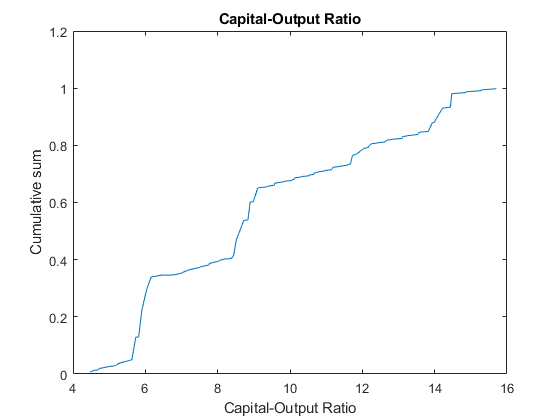

output = Policy.Asset.Values .^ eco_param.alpha + Policy.Labor.Values .^ (1-eco_param.alpha);

capital_output = Policy.Asset.Values ./ output;

[sortedK, indexK] = sort(capital_output(:));
lambda_aux = Lambda(:);

figure
plot(sortedK, cumsum(lambda_aux(indexK)));
title('Capital-Output Ratio');
xlabel('Capital-Output Ratio');
ylabel('Cumulative sum');

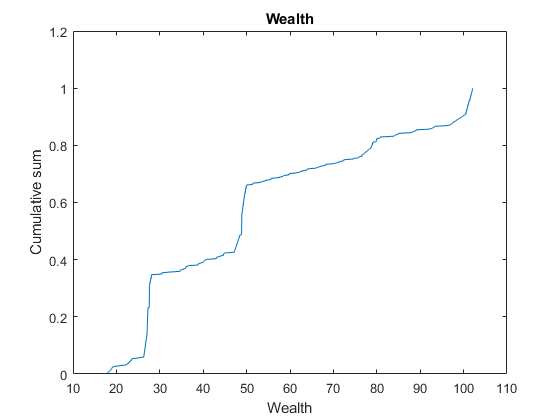



[sortedK, indexK] = sort(Policy.Wealth.Values(:));
lambda_aux = Lambda(:);
figure
plot(sortedK, cumsum(lambda_aux(indexK)));
title('Wealth');
xlabel('Wealth');
ylabel('Cumulative sum');